close all
clear all

step = 0.2;
n = 21;
K1 = 350;
K3 = 200;
T = 100000;
beta = 1E-6;



% Pre-allocate matrices
sigma = 2 * rand(n) - 1; % random matrix with -1, 1
sigma = sigma * 2 * pi;
%sigma = flipud(sigma);


s3sum=0;

% Initial energy calculation
[S, E, sumdata] = compute_interactions(sigma, n, step, K1, K3, T);

E(1)-E(2)

ans = 0


E(T)

ans = 511.8051

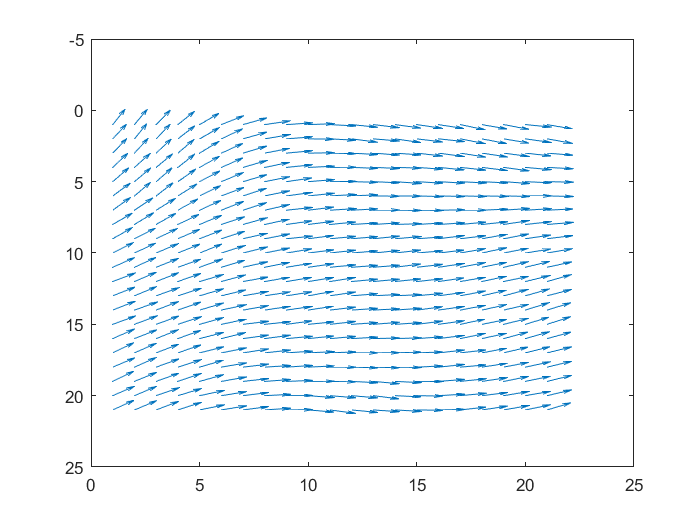


kasper=exp(-(E(1)-E(2)));

figure(1); quiver(cos(S),sin(S))
set (gca,'Ydir','reverse')


% Simulation data collection
SimData = flipud(S); 

% Save data
save('Simulation_data.mat', 'SimData');



% Plotting
load('Simulation_data.mat');
SimData;


% Function to calculate the interaction terms

function [S, E, sumdata, k, deltaE] = compute_interactions(sigma, n, step , K1, K3, T)



E = zeros(1, T+1);        % Sikrer, at E er allokeret til alle iterationer
deltaE = zeros(1, T+1);   % Sikrer, at deltaE er allokeret korrekt
sumdata = zeros(1, T+1);  % Sikrer, at sumdata er forudallokeret
 

for k=2:T+1
  
    R1 = randi([1, n]);
    R2 = randi([1, n]);   
    R3 = randi([1, n]);
    R4 = randi([1, n]);
    
    deltax = step*randn;
    
    % Flip a random spin
    if k>2
    sigma(R3, R4) = sigma(R3, R4) + deltax;
    end
    n = size(sigma, 1);
    
    
    % Calculate interaction terms
dx = zeros(n, n);
dx(:, 1:end-1) = sigma(:, 2:end) - sigma(:, 1:end-1);

% dy: forskel i y-retningen (nedadgående nabo)
dy = zeros(n, n);
dy(1:end-1, :) = sigma(2:end, :) - sigma(1:end-1, :);

% Beregn de to termer i summen
term1_sum = 1/2*sum(K1*(dx.^2+dy.^2), "all");

term2_sum = 1/2*sum((K3-K1)*(1/2*cos(2*sigma(:, 1:end)).* dx.^2 + 1/2*sin(2*sigma(1:end, :)).* dy.^2), "all");
% Samlet udtryk
E(k) = term1_sum + term2_sum;


S=sigma;

    %E(k) = K * sum(P, "all") + K * alpha * sum(cos(2 * (sigma(1, :))),"all");
    
    if k==2
      
    sigma(R1, R2) = sigma(R1, R2) + deltax;
    
    % Calculate interaction terms
dx = zeros(n, n);
dx(:, 1:end-1) = sigma(:, 2:end) - sigma(:, 1:end-1);

% dy: forskel i y-retningen (nedadgående nabo)
dy = zeros(n, n);
dy(1:end-1, :) = sigma(2:end, :) - sigma(1:end-1, :);

% Beregn de tre termer i summen
term1_sum = 1/2*sum(K1*(dx.^2+dy.^2), "all");

term2_sum = 1/2*sum((K3-K1)*(1/2*cos(2*sigma(:, 1:end)).* dx.^2 + 1/2*sin(2*sigma(1:end, :)).* dy.^2), "all");
% Samlet udtryk
E(k-1) = term1_sum + term2_sum;

S=sigma;

    %E(k) = K * sum(P, "all") + K * alpha * sum(cos(2 * (sigma(1, :))),"all");
    deltaE(k) = E(k-1) - E(k);
    
    if rand < exp(-deltaE(k))
        E(k) = E(k)+deltaE(k);
    else
        % Revert the flip if energy does not decrease
        sigma(R1, R2) = sigma(R1, R2) - deltax;
    end
    end
    
    
    if k>2
    deltaE(k) = E(k) - E(k-1);
    
    if rand < exp(-deltaE(k))
        E(k)=E(k)+deltaE(k);
    else
        % Revert the flip if energy does not decrease
        sigma(R3, R4) = sigma(R3, R4) - deltax;
    end
    end
    % Calculate interaction terms
dx = zeros(n, n);
dx(:, 1:end-1) = sigma(:, 2:end) - sigma(:, 1:end-1);

% dy: forskel i y-retningen (nedadgående nabo)
dy = zeros(n, n);
dy(1:end-1, :) = sigma(2:end, :) - sigma(1:end-1, :);

% Beregn de tre termer i summen
term1_sum = 1/2*sum(K1*(dx.^2+dy.^2), "all");

term2_sum = 1/2*sum((K3-K1)*(1/2*cos(2*sigma(:, 1:end)).* dx.^2 + 1/2*sin(2*sigma(1:end, :)).* dy.^2), "all");
% Samlet udtryk
E(k) = term1_sum + term2_sum;

S=sigma;
    %E(k) = K * sum(P, "all") + K * alpha * sum(cos(2 * (sigma(1, :))),"all");
    sumdata(k)=sum(S,"all");
    deltaE(k) = E(k-1) - E(k);
end
end



